### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

clear cast*
% Pick align_sec
a1 = 4;
align_sec = a1; 

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year1')
% addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1\From_Leah')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')

btl = readtable('Irminger_Sea-01_KN221-04_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum02CTD1 = btl(btl.Cast == 2,:);
btlsum03CTD1 = btl(btl.Cast == 3,:);
btlsum04CTD1 = btl(btl.Cast == 4,:);
btlsum05CTD1 = btl(btl.Cast == 5,:);
btlsum06CTD1 = btl(btl.Cast == 6,:);
btlsum07CTD1 = btl(btl.Cast == 7,:);
btlsum09CTD1 = btl(btl.Cast == 9,:);

btlsum02CTD2 = btl(btl.Cast == 2,:);
btlsum03CTD2 = btl(btl.Cast == 3,:);
btlsum04CTD2 = btl(btl.Cast == 4,:);
btlsum05CTD2 = btl(btl.Cast == 5,:);
btlsum06CTD2 = btl(btl.Cast == 6,:);
btlsum07CTD2 = btl(btl.Cast == 7,:);
btlsum09CTD2 = btl(btl.Cast == 9,:);

btlsum02CTD1 = combine_btl_files_woutCTDcal('KN22104002.csv',btlsum02CTD1);

btlsum03CTD1 = combine_btl_files_woutCTDcal('KN22104003.csv',btlsum03CTD1);

btlsum04CTD1 = combine_btl_files_woutCTDcal('KN22104004.csv',btlsum04CTD1);

btlsum05CTD1 = combine_btl_files_woutCTDcal('KN22104005.csv',btlsum05CTD1);

btlsum06CTD1 = combine_btl_files_woutCTDcal('KN22104006.csv',btlsum06CTD1);

btlsum07CTD1 = combine_btl_files_woutCTDcal('KN22104007.csv',btlsum07CTD1);

btlsum09CTD1 = combine_btl_files_woutCTDcal('KN22104009.csv',btlsum09CTD1);


btlsum02CTD2 = combine_btl_files_woutCTDcal('KN22104002.csv',btlsum02CTD2);

btlsum03CTD2 = combine_btl_files_woutCTDcal('KN22104003.csv',btlsum03CTD2);

btlsum04CTD2 = combine_btl_files_woutCTDcal('KN22104004.csv',btlsum04CTD2);

btlsum05CTD2 = combine_btl_files_woutCTDcal('KN22104005.csv',btlsum05CTD2);

btlsum06CTD2 = combine_btl_files_woutCTDcal('KN22104006.csv',btlsum06CTD2);

btlsum07CTD2 = combine_btl_files_woutCTDcal('KN22104007.csv',btlsum07CTD2);

btlsum09CTD2 = combine_btl_files_woutCTDcal('KN22104009.csv',btlsum09CTD2);


%% If get finalized finalsfrom Leah 
% btlsum02 = combine_btl_files('KN22104002.cbot_s','KN22104002.csv',btlsum02,CTD_sen1);
% btlsum03 = combine_btl_files('KN22104003.cbot_s','KN22104003.csv',btlsum03,CTD_sen1);
% btlsum04 = combine_btl_files('KN22104004.cbot_s','KN22104004.csv',btlsum04,CTD_sen1);
% btlsum05 = combine_btl_files('KN22104005.cbot_s','KN22104005.csv',btlsum05,CTD_sen1);
% btlsum06 = combine_btl_files('KN22104006.cbot_s','KN22104006.csv',btlsum06,CTD_sen1);
% btlsum07 = combine_btl_files('KN22104007.cbot_s','KN22104007.csv',btlsum07,CTD_sen1);
% btlsum09 = combine_btl_files('KN22104009.cbot_s','KN22104009.csv',btlsum09,CTD_sen1);

btlsum_yr1 = [btlsum02CTD1; btlsum03CTD1; btlsum04CTD1; btlsum05CTD1; btlsum06CTD1; btlsum07CTD1; btlsum09CTD1];
btlsum0 = btlsum_yr1; %

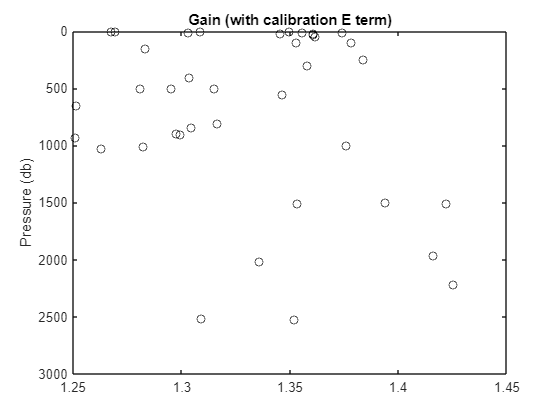

figure % Winkler/CTD Oxygen (without Leah calibrated Sal product)
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Oxygen Sensor for cast 2 on; different one cast 1  
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.55930e-001);
cal.VOFFSET = double(-4.97100e-001);
cal.A = double(-3.66900e-003);
cal.B = double(1.91110e-004);
cal.C = double(-2.62760e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(2.23000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '1679';
cal.OCALDATE = '23-Oct-13';

H = [-0.033, 5000, 1450]; % Default 

cal1 = cal;
cal2 = cal;

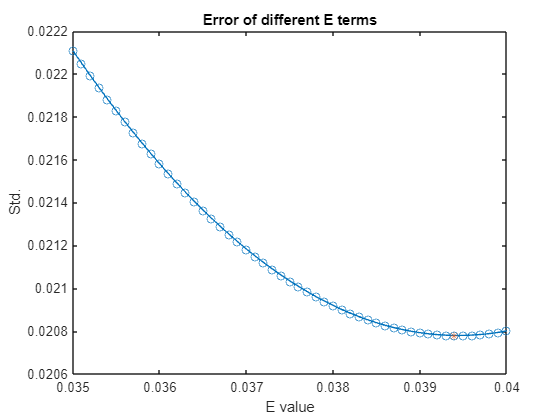

cal.E2 = 0.0394


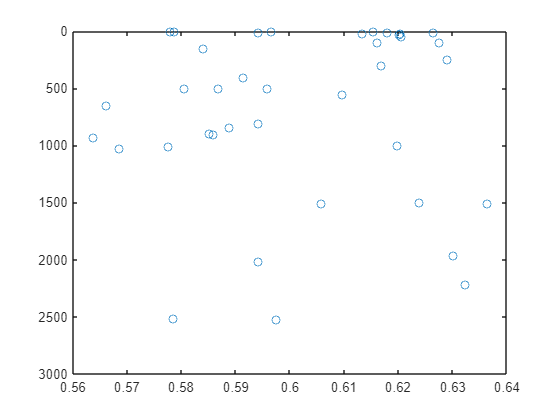

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
CTD_sen1 = 1;
CTD_sen2 = 2;
btlsum0.CTDoxy_mLL_cal = btlsum0.CTDoxy_mLL; % Because don't have cal product

[cal1] = E2_calculation(btlsum0,cal1,CTD_sen1); % Use dummy bottle summary with outlier removed

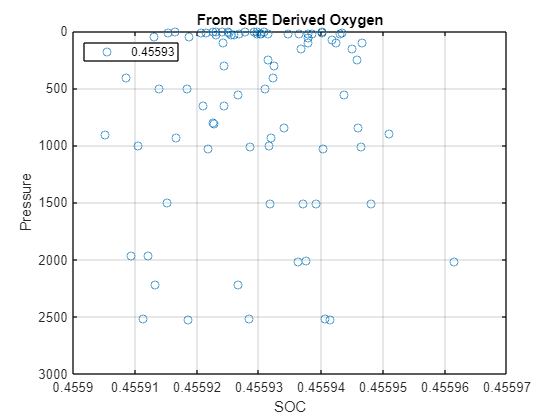

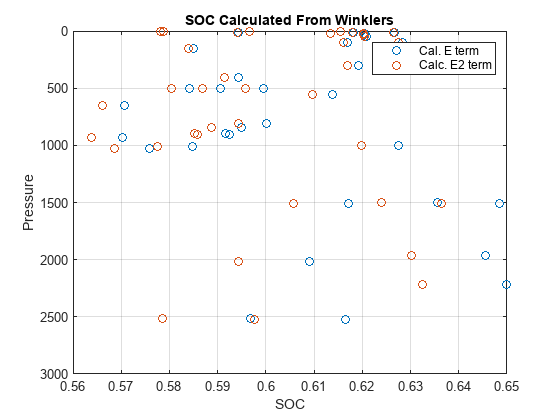

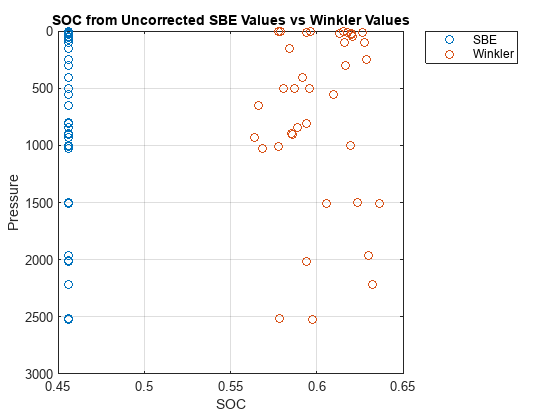

New SOC = 0.60182
EGain = 1.32+/- 0.045577



[cal1] = Gain_E2_Calculation(btlsum0,cal1,CTD_sen1); % Use dummy bottle summary with any outliers removed

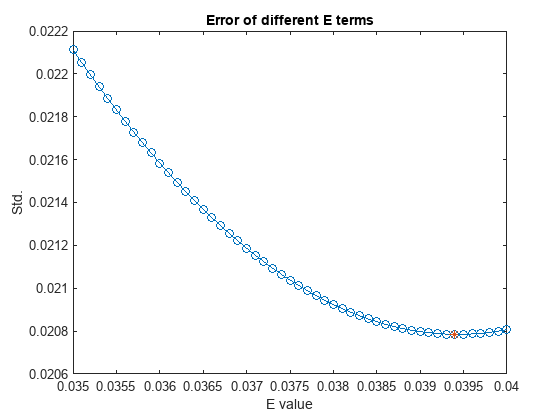

cal.E2 = 0.0394


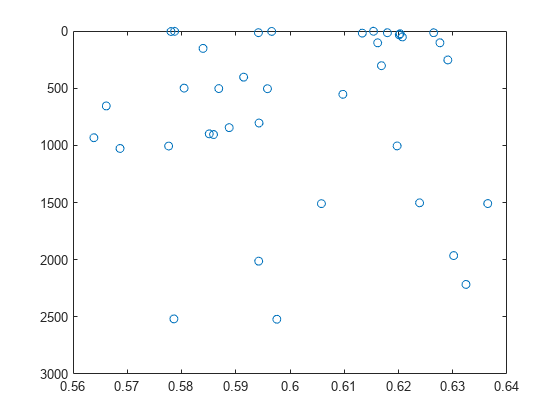


[cal2] = E2_calculation(btlsum0,cal2,CTD_sen2); % Use dummy bottle summary with outlier removed

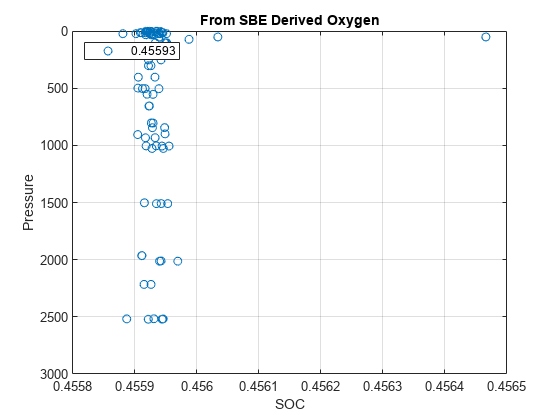

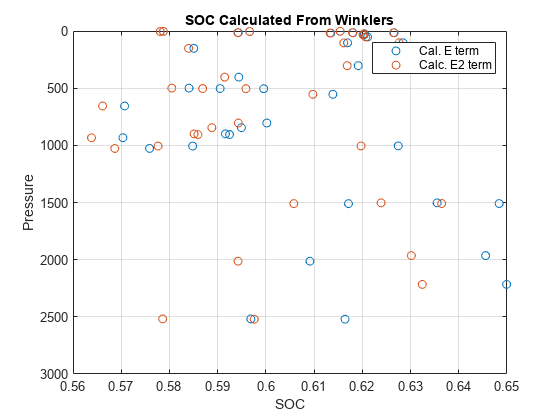

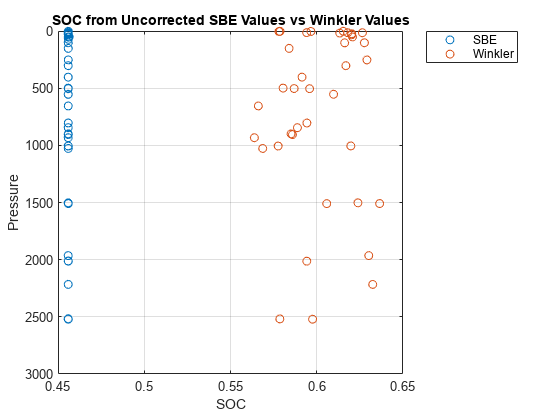

New SOC = 0.60182
EGain = 1.32+/- 0.045588



[cal2] = Gain_E2_Calculation(btlsum0,cal2,CTD_sen2); % Use dummy bottle summary with any outliers removed

% Read in processed casts
% Processed with 4 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
cast02uCTD1 = readSBScnv( 'uKN22104002.cnv' );
cast03uCTD1 = readSBScnv( 'uKN22104003.cnv' );
cast04uCTD1 = readSBScnv( 'uKN22104004.cnv' );
cast05uCTD1 = readSBScnv( 'uKN22104005.cnv' );
cast06uCTD1 = readSBScnv( 'uKN22104006.cnv' );
cast07uCTD1 = readSBScnv( 'uKN22104007.cnv' );
cast08uCTD1 = readSBScnv( 'uKN22104008.cnv' );
cast09uCTD1 = readSBScnv( 'uKN22104009.cnv' );

cast02dCTD1 = readSBScnv( 'dKN22104002.cnv' );
cast03dCTD1 = readSBScnv( 'dKN22104003.cnv' );
cast04dCTD1 = readSBScnv( 'dKN22104004.cnv' );
cast05dCTD1 = readSBScnv( 'dKN22104005.cnv' );
cast06dCTD1 = readSBScnv( 'dKN22104006.cnv' );
cast07dCTD1 = readSBScnv( 'dKN22104007.cnv' );
cast08dCTD1 = readSBScnv( 'dKN22104008.cnv' );
cast09dCTD1 = readSBScnv( 'dKN22104009.cnv' );

cast02uCTD2 = readSBScnv( 'uKN22104002.cnv' );
cast03uCTD2 = readSBScnv( 'uKN22104003.cnv' );
cast04uCTD2 = readSBScnv( 'uKN22104004.cnv' );
cast05uCTD2 = readSBScnv( 'uKN22104005.cnv' );
cast06uCTD2 = readSBScnv( 'uKN22104006.cnv' );
cast07uCTD2 = readSBScnv( 'uKN22104007.cnv' );
cast08uCTD2 = readSBScnv( 'uKN22104008.cnv' );
cast09uCTD2 = readSBScnv( 'uKN22104009.cnv' );

cast02dCTD2 = readSBScnv( 'dKN22104002.cnv' );
cast03dCTD2 = readSBScnv( 'dKN22104003.cnv' );
cast04dCTD2 = readSBScnv( 'dKN22104004.cnv' );
cast05dCTD2 = readSBScnv( 'dKN22104005.cnv' );
cast06dCTD2 = readSBScnv( 'dKN22104006.cnv' );
cast07dCTD2 = readSBScnv( 'dKN22104007.cnv' );
cast08dCTD2 = readSBScnv( 'dKN22104008.cnv' );
cast09dCTD2 = readSBScnv( 'dKN22104009.cnv' );

% % Format to table without Leah's product 
% [cast02u, cast02u0] = combine_CTD_files_woutCTDcal(cast02u); [cast02d, cast02d0] = combine_CTD_files_woutCTDcal(cast02d);  
% [cast03u, cast03u0] = combine_CTD_files_woutCTDcal(cast03u); [cast03d, cast03d0] = combine_CTD_files_woutCTDcal(cast03d);  
% [cast04u, cast04u0] = combine_CTD_files_woutCTDcal(cast04u); [cast04d, cast04d0] = combine_CTD_files_woutCTDcal(cast04d);  
% [cast05u, cast05u0] = combine_CTD_files_woutCTDcal(cast05u); [cast05d, cast05d0] = combine_CTD_files_woutCTDcal(cast05d);  
% [cast06u, cast06u0] = combine_CTD_files_woutCTDcal(cast06u); [cast06d, cast06d0] = combine_CTD_files_woutCTDcal(cast06d);  
% [cast07u, cast07u0] = combine_CTD_files_woutCTDcal(cast07u); [cast07d, cast07d0] = combine_CTD_files_woutCTDcal(cast07d);  
% [cast08u, cast08u0] = combine_CTD_files_woutCTDcal(cast08u); [cast08d, cast08d0] = combine_CTD_files_woutCTDcal(cast08d);  
% [cast09u, cast09u0] = combine_CTD_files_woutCTDcal(cast09u); [cast09d, cast09d0] = combine_CTD_files_woutCTDcal(cast09d);  


% Format to table without Leah's product 
[cast02uCTD1, ~] = combine_CTD_files_woutCTDcal(cast02uCTD1); [cast02dCTD1, ~] = combine_CTD_files_woutCTDcal(cast02dCTD1);  
[cast03uCTD1, ~] = combine_CTD_files_woutCTDcal(cast03uCTD1); [cast03dCTD1, ~] = combine_CTD_files_woutCTDcal(cast03dCTD1);  
[cast04uCTD1, ~] = combine_CTD_files_woutCTDcal(cast04uCTD1); [cast04dCTD1, ~] = combine_CTD_files_woutCTDcal(cast04dCTD1);  
[cast05uCTD1, ~] = combine_CTD_files_woutCTDcal(cast05uCTD1); [cast05dCTD1, ~] = combine_CTD_files_woutCTDcal(cast05dCTD1);  
[cast06uCTD1, ~] = combine_CTD_files_woutCTDcal(cast06uCTD1); [cast06dCTD1, ~] = combine_CTD_files_woutCTDcal(cast06dCTD1);  
[cast07uCTD1, ~] = combine_CTD_files_woutCTDcal(cast07uCTD1); [cast07dCTD1, ~] = combine_CTD_files_woutCTDcal(cast07dCTD1);  
[cast08uCTD1, ~] = combine_CTD_files_woutCTDcal(cast08uCTD1); [cast08dCTD1, ~] = combine_CTD_files_woutCTDcal(cast08dCTD1);  
[cast09uCTD1, ~] = combine_CTD_files_woutCTDcal(cast09uCTD1); [cast09dCTD1, ~] = combine_CTD_files_woutCTDcal(cast09dCTD1);  

% Format to table without Leah's product 
[cast02uCTD2, ~] = combine_CTD_files_woutCTDcal(cast02uCTD2); [cast02dCTD2, ~] = combine_CTD_files_woutCTDcal(cast02dCTD2);  
[cast03uCTD2, ~] = combine_CTD_files_woutCTDcal(cast03uCTD2); [cast03dCTD2, ~] = combine_CTD_files_woutCTDcal(cast03dCTD2);  
[cast04uCTD2, ~] = combine_CTD_files_woutCTDcal(cast04uCTD2); [cast04dCTD2, ~] = combine_CTD_files_woutCTDcal(cast04dCTD2);  
[cast05uCTD2, ~] = combine_CTD_files_woutCTDcal(cast05uCTD2); [cast05dCTD2, ~] = combine_CTD_files_woutCTDcal(cast05dCTD2);  
[cast06uCTD2, ~] = combine_CTD_files_woutCTDcal(cast06uCTD2); [cast06dCTD2, ~] = combine_CTD_files_woutCTDcal(cast06dCTD2);  
[cast07uCTD2, ~] = combine_CTD_files_woutCTDcal(cast07uCTD2); [cast07dCTD2, ~] = combine_CTD_files_woutCTDcal(cast07dCTD2);  
[cast08uCTD2, ~] = combine_CTD_files_woutCTDcal(cast08uCTD2); [cast08dCTD2, ~] = combine_CTD_files_woutCTDcal(cast08dCTD2);  
[cast09uCTD2, ~] = combine_CTD_files_woutCTDcal(cast09uCTD2); [cast09dCTD2, ~] = combine_CTD_files_woutCTDcal(cast09dCTD2);  


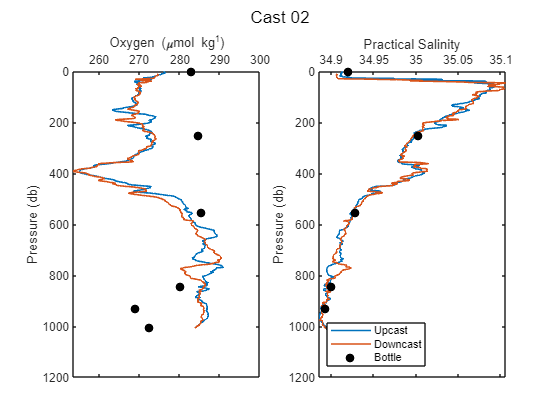

% Using function written for missing final Sal product 
sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_woutCTDcal(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)

[cast02uCTD1, cast02dCTD1, btlsum02CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast02uCTD1,cast02dCTD1,cal1,btlsum02CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 02');

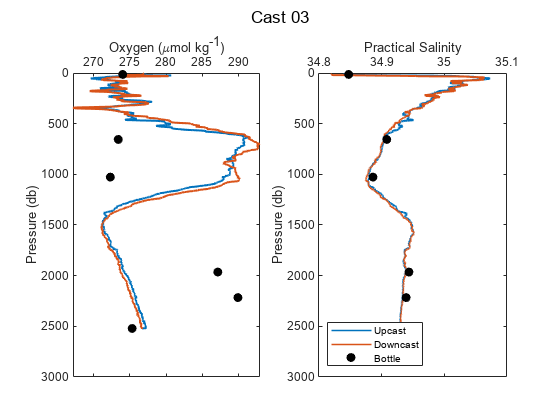

[cast03uCTD1, cast03dCTD1, btlsum03CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast03uCTD1,cast03dCTD1,cal1,btlsum03CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 03');

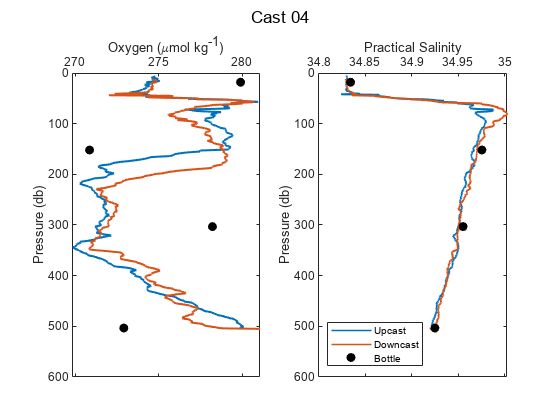

[cast04uCTD1, cast04dCTD1, btlsum04CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast04uCTD1,cast04dCTD1,cal1,btlsum04CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 04');

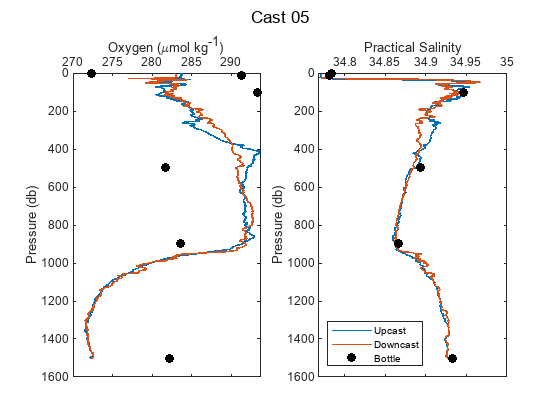

[cast05uCTD1, cast05dCTD1, btlsum05CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast05uCTD1,cast05dCTD1,cal1,btlsum05CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 05');

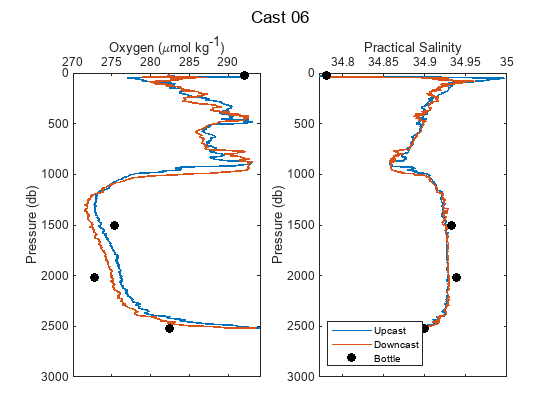

[cast06uCTD1, cast06dCTD1, btlsum06CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast06uCTD1,cast06dCTD1,cal1,btlsum06CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 06');

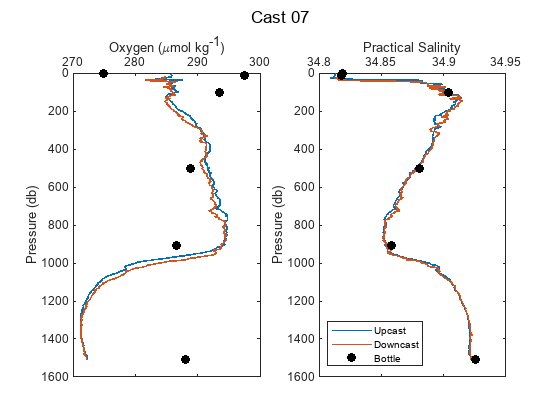

[cast07uCTD1, cast07dCTD1, btlsum07CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast07uCTD1,cast07dCTD1,cal1,btlsum07CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 07');

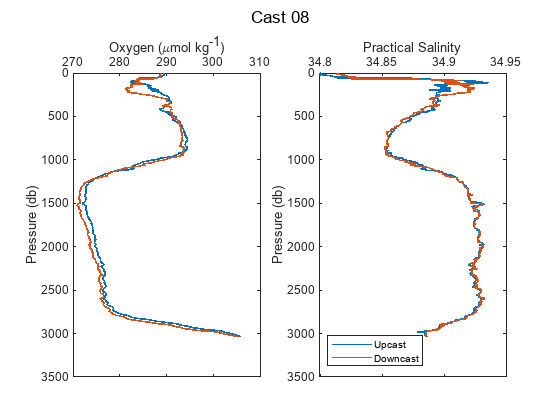

[cast08uCTD1, cast08dCTD1, btlsum08CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast08uCTD1,cast08dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 08');

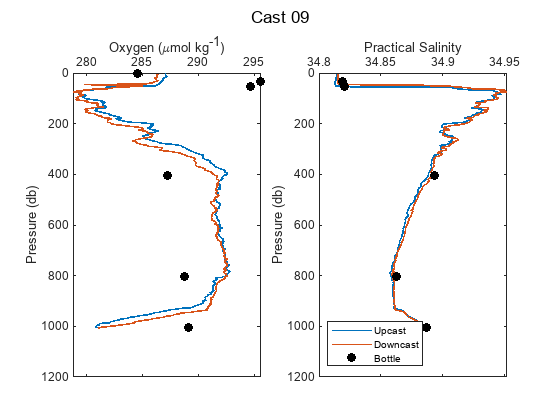

[cast09uCTD1, cast09dCTD1, btlsum09CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast09uCTD1,cast09dCTD1,cal1,btlsum09CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 09');

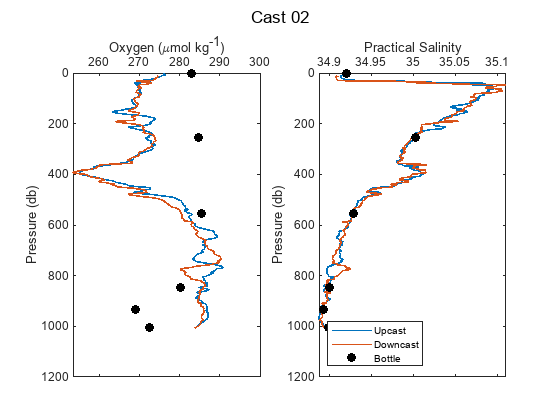


[cast02uCTD2, cast02dCTD2, btlsum02CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast02uCTD2,cast02dCTD2,cal2,btlsum02CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 02');

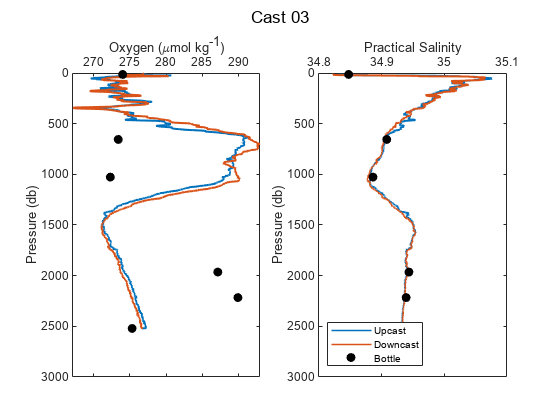

[cast03uCTD2, cast03dCTD2, btlsum03CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast03uCTD2,cast03dCTD2,cal2,btlsum03CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 03');

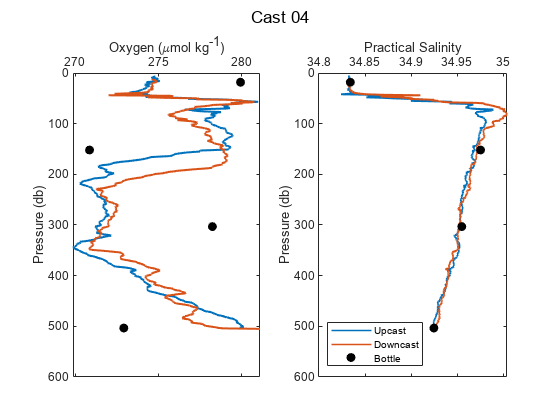

[cast04uCTD2, cast04dCTD2, btlsum04CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast04uCTD2,cast04dCTD2,cal2,btlsum04CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 04');

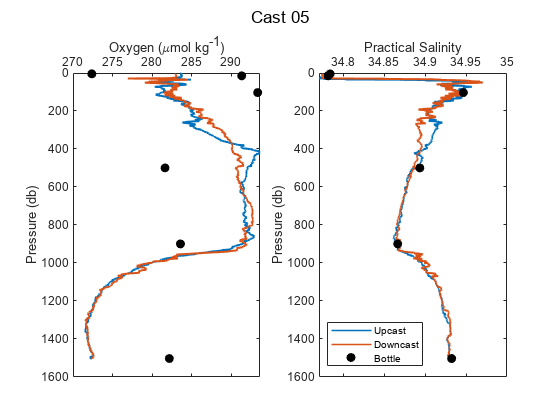

[cast05uCTD2, cast05dCTD2, btlsum05CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast05uCTD2,cast05dCTD2,cal2,btlsum05CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 05');

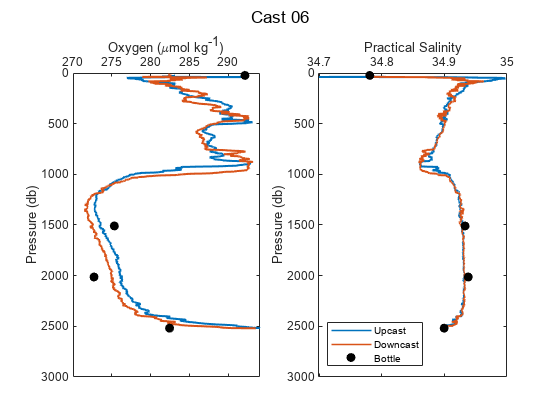

[cast06uCTD2, cast06dCTD2, btlsum06CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast06uCTD2,cast06dCTD2,cal2,btlsum06CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 06');

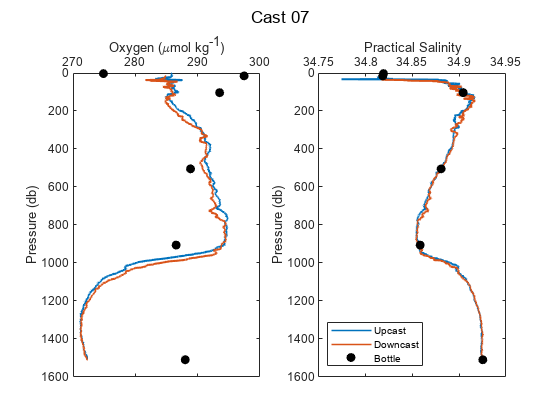

[cast07uCTD2, cast07dCTD2, btlsum07CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast07uCTD2,cast07dCTD2,cal2,btlsum07CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 07');

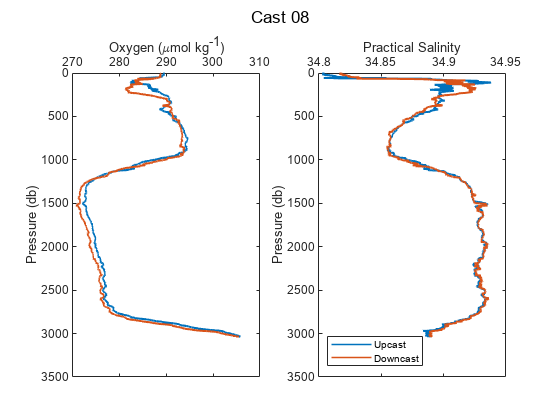

[cast08uCTD2, cast08dCTD2, btlsum08CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast08uCTD2,cast08dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 08');

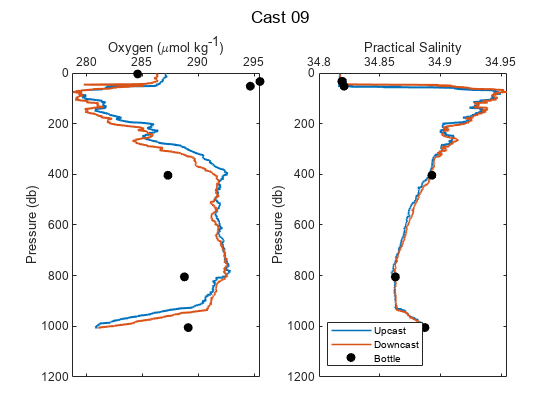

[cast09uCTD2, cast09dCTD2, btlsum09CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast09uCTD2,cast09dCTD2,cal2,btlsum09CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 09');

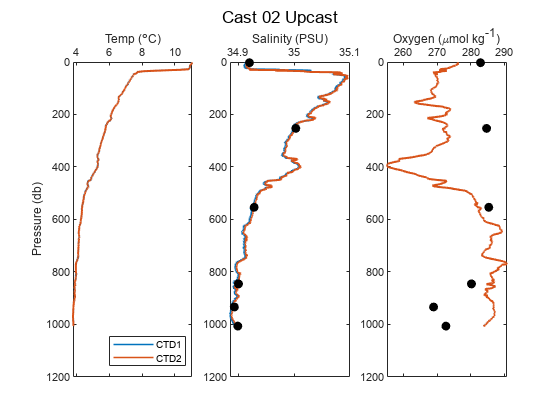

DO1 - DO2 = 0.0027179 +/- 0.00066963 umol/kg
Sal1 - Sal2 = 0.0026031 +/- 0.0032458 PSU



[DOdiff02u, DOstd02] = CTD1vsCTD2(cast02uCTD1,cast02uCTD2,btlsum02CTD1,'Cast 02 Upcast');

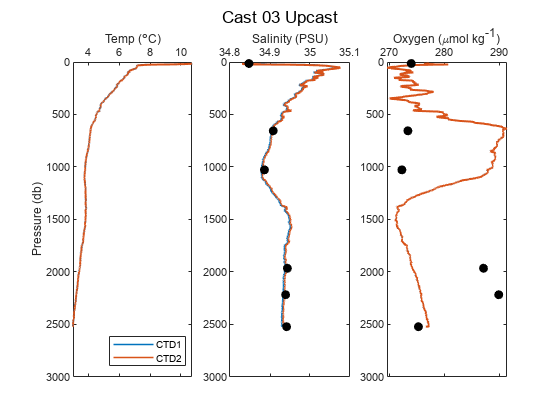

DO1 - DO2 = 0.0026282 +/- 0.0005263 umol/kg
Sal1 - Sal2 = 0.0028188 +/- 0.0024421 PSU


[DOdiff03u, DOstd03] = CTD1vsCTD2(cast03uCTD1,cast03uCTD2,btlsum03CTD1,'Cast 03 Upcast');

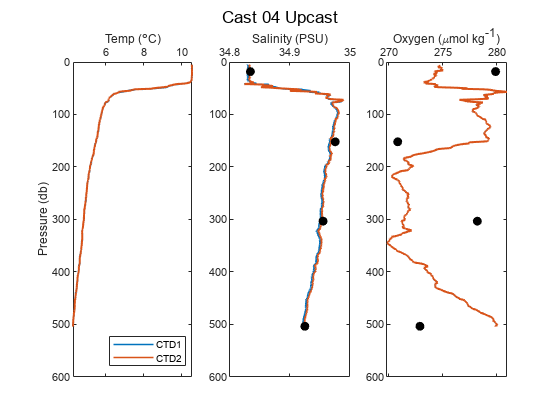

DO1 - DO2 = 0.0027639 +/- 0.0005605 umol/kg
Sal1 - Sal2 = 0.0023944 +/- 0.0026038 PSU


[DOdiff04u, DOstd04] = CTD1vsCTD2(cast04uCTD1,cast04uCTD2,btlsum04CTD1,'Cast 04 Upcast');

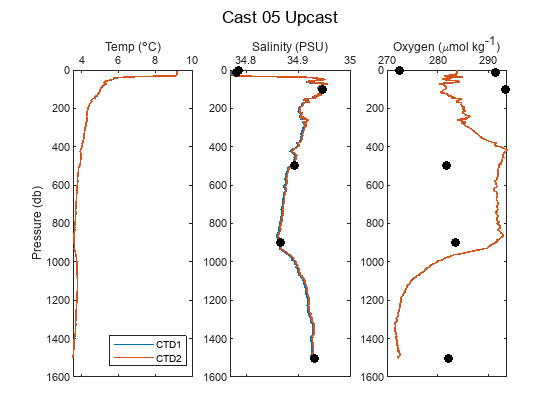

DO1 - DO2 = 0.002699 +/- 0.00043081 umol/kg
Sal1 - Sal2 = 0.0027674 +/- 0.0019355 PSU


[DOdiff05u, DOstd05] = CTD1vsCTD2(cast05uCTD1,cast05uCTD2,btlsum05CTD1,'Cast 05 Upcast');

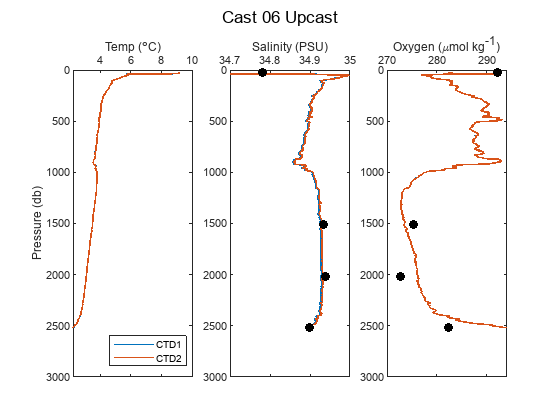

DO1 - DO2 = 0.0026582 +/- 0.0009279 umol/kg
Sal1 - Sal2 = 0.0028794 +/- 0.0041413 PSU


[DOdiff06u, DOstd06] = CTD1vsCTD2(cast06uCTD1,cast06uCTD2,btlsum06CTD1,'Cast 06 Upcast');

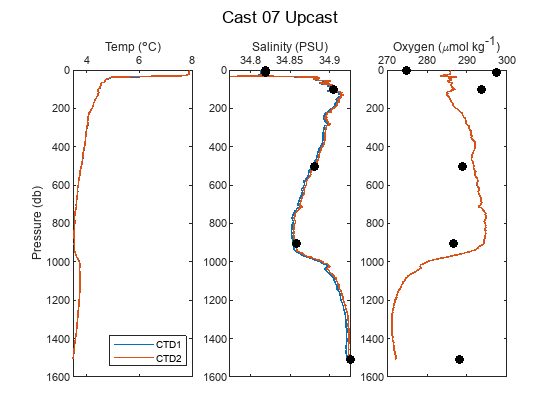

DO1 - DO2 = 0.0026926 +/- 0.00039887 umol/kg
Sal1 - Sal2 = 0.0027282 +/- 0.0017378 PSU


[DOdiff07u, DOstd07] = CTD1vsCTD2(cast07uCTD1,cast07uCTD2,btlsum07CTD1,'Cast 07 Upcast');

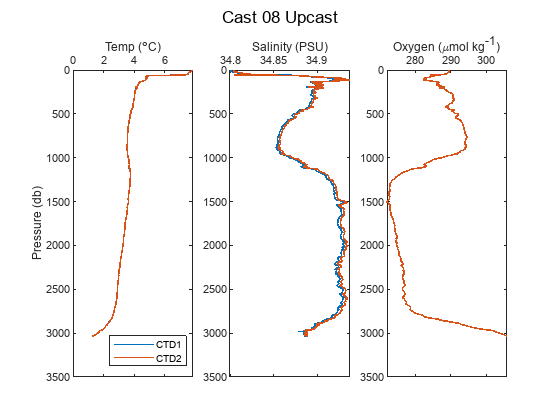

DO1 - DO2 = 0.0026055 +/- 0.00040656 umol/kg
Sal1 - Sal2 = 0.0030081 +/- 0.0017468 PSU


[DOdiff08u, DOstd08] = CTD1vsCTD2(cast08uCTD1,cast08uCTD2,btlsum08CTD1,'Cast 08 Upcast');

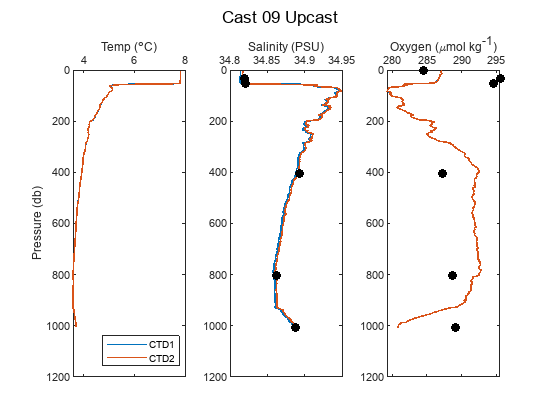

DO1 - DO2 = 0.0028082 +/- 0.00039492 umol/kg
Sal1 - Sal2 = 0.002416 +/- 0.0018206 PSU


[DOdiff09u, DOstd09] = CTD1vsCTD2(cast09uCTD1,cast09uCTD2,btlsum09CTD1,'Cast 09 Upcast');

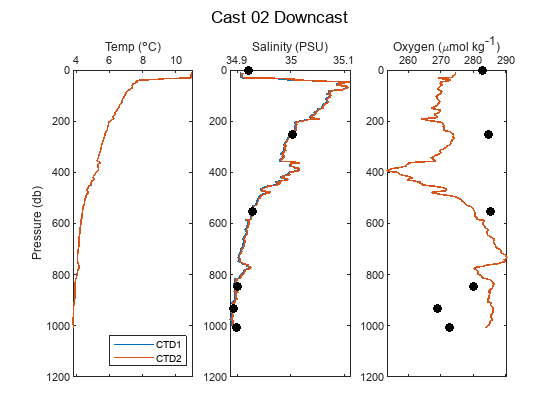

DO1 - DO2 = 0.0026912 +/- 0.00034099 umol/kg
Sal1 - Sal2 = 0.0022972 +/- 0.0015824 PSU



[DOdiff02d, DOstd02] = CTD1vsCTD2(cast02dCTD1,cast02dCTD2,btlsum02CTD1,'Cast 02 Downcast');

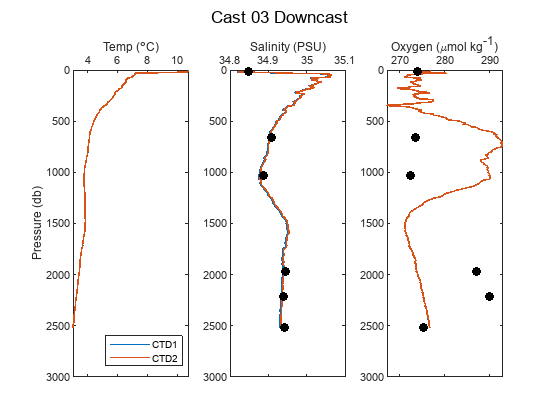

DO1 - DO2 = 0.0026516 +/- 0.00024093 umol/kg
Sal1 - Sal2 = 0.0025146 +/- 0.0010225 PSU


[DOdiff03d, DOstd03] = CTD1vsCTD2(cast03dCTD1,cast03dCTD2,btlsum03CTD1,'Cast 03 Downcast');

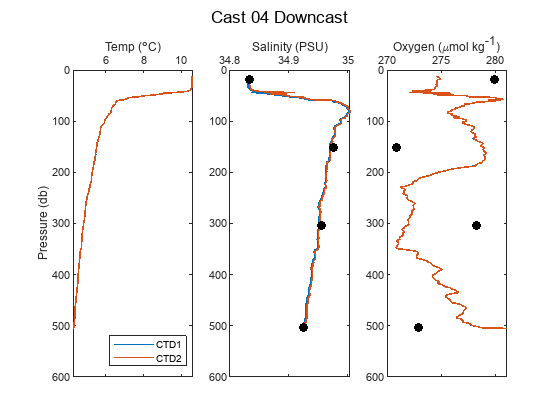

DO1 - DO2 = 0.002724 +/- 0.00082281 umol/kg
Sal1 - Sal2 = 0.0023325 +/- 0.0039533 PSU


[DOdiff04d, DOstd04] = CTD1vsCTD2(cast04dCTD1,cast04dCTD2,btlsum04CTD1,'Cast 04 Downcast');

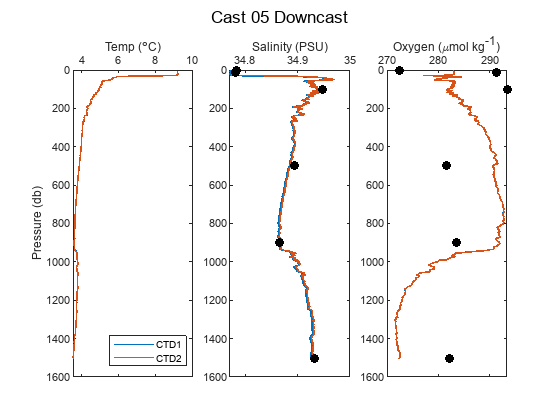

DO1 - DO2 = 0.0027311 +/- 0.00040177 umol/kg
Sal1 - Sal2 = 0.0024663 +/- 0.001775 PSU


[DOdiff05d, DOstd05] = CTD1vsCTD2(cast05dCTD1,cast05dCTD2,btlsum05CTD1,'Cast 05 Downcast');

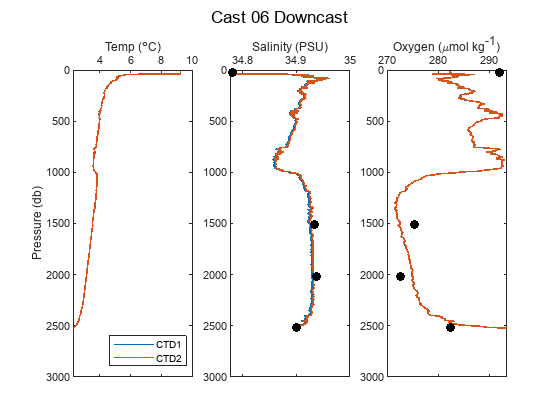

DO1 - DO2 = 0.0026538 +/- 0.00036483 umol/kg
Sal1 - Sal2 = 0.0026402 +/- 0.0015878 PSU


[DOdiff06d, DOstd06] = CTD1vsCTD2(cast06dCTD1,cast06dCTD2,btlsum06CTD1,'Cast 06 Downcast');

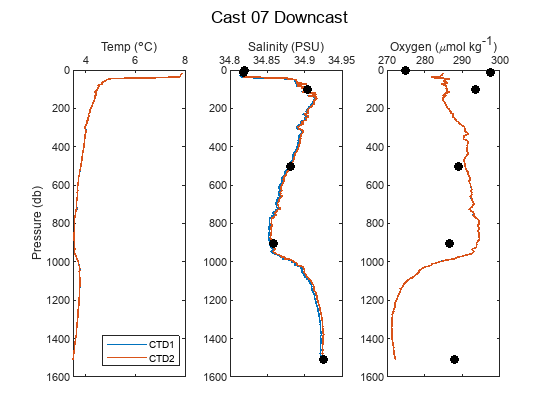

DO1 - DO2 = 0.0027187 +/- 0.00034492 umol/kg
Sal1 - Sal2 = 0.0025321 +/- 0.0014765 PSU


[DOdiff07d, DOstd07] = CTD1vsCTD2(cast07dCTD1,cast07dCTD2,btlsum07CTD1,'Cast 07 Downcast');

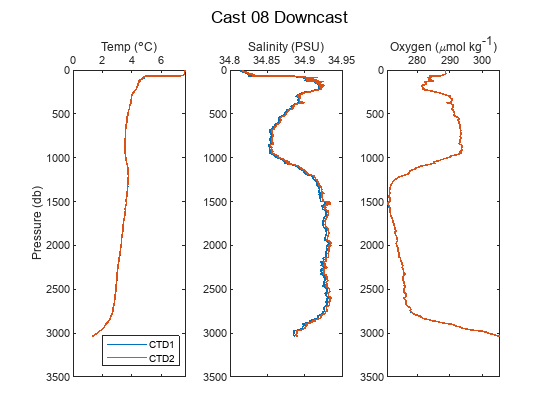

DO1 - DO2 = 0.0025846 +/- 0.00023362 umol/kg
Sal1 - Sal2 = 0.0029379 +/- 0.00092451 PSU


[DOdiff08d, DOstd08] = CTD1vsCTD2(cast08dCTD1,cast08dCTD2,btlsum08CTD1,'Cast 08 Downcast');

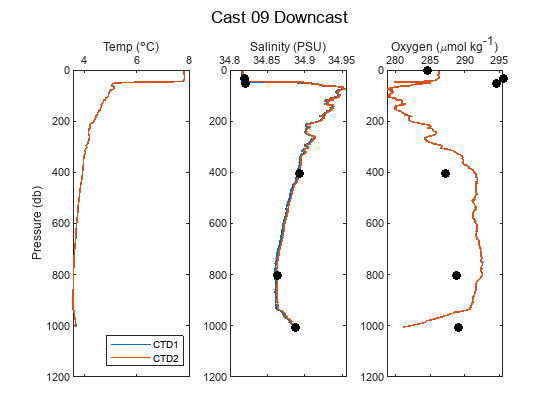

DO1 - DO2 = 0.0028251 +/- 0.00035585 umol/kg
Sal1 - Sal2 = 0.0022307 +/- 0.0016281 PSU


[DOdiff09d, DOstd09] = CTD1vsCTD2(cast09dCTD1,cast09dCTD2,btlsum09CTD1,'Cast 09 Downcast');



DOdiff = [DOdiff02u DOdiff03u DOdiff04u DOdiff05u DOdiff06u...
    DOdiff07u DOdiff08u DOdiff09u...
    DOdiff02d DOdiff03d DOdiff04d DOdiff05d DOdiff06d...
    DOdiff07d DOdiff08d DOdiff09d];
nanmean(abs(DOdiff))

ans = 0.0027

nanstd(DOdiff)

ans = 6.6970e-05

% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
% clear btlsum0 btl
% dt_Processed = datetime;
% save Year1_CTD1vsCTD2_KF cast*

function [DOdiff, DOstd] = CTD1vsCTD2(castCTD1,castCTD2,btlsumCTD,CastString)

    figure
    subplot(1,3,1)
    plot(castCTD1.temp1,castCTD1.prs,'Linewidth',1.2)
    hold on
    plot(castCTD2.temp2,castCTD2.prs,'Linewidth',1.2)
    axis ij
    ylabel('Pressure (db)')
    xlabel('Temp (\circC)')
    ax = gca;
    ax.XAxisLocation = 'top';
    legend('CTD1','CTD2','Location','SE')

    subplot(1,3,2)
    plot(castCTD1.sal1,castCTD1.prs,'Linewidth',1.2)
    hold on
    plot(castCTD2.sal2,castCTD2.prs,'Linewidth',1.2)
    if height(btlsumCTD) ~= 1
        plot(btlsumCTD.Discrete_Salinity_psu,btlsumCTD.prs,'ok','MarkerFaceColor','k')
    end
    axis ij
    xlabel('Salinity (PSU)')
    ax = gca;
    ax.XAxisLocation = 'top';
    
    subplot(1,3,3)
    plot(castCTD1.DOcorr_umolkg,castCTD1.prs,'Linewidth',1.2)
    hold on
    plot(castCTD2.DOcorr_umolkg,castCTD2.prs,'Linewidth',1.2)
    if height(btlsumCTD) ~= 1
        plot(btlsumCTD.Winkler_umolkg,btlsumCTD.prs,'ok','MarkerFaceColor','k')
    end
    axis ij
    xlabel('Oxygen (\mumol kg^-^1)')
    ax = gca;
    ax.XAxisLocation = 'top';
    sgtitle(CastString)

    DOdiff = nanmean(abs(castCTD1.DOcorr_umolkg-castCTD2.DOcorr_umolkg));
    DOstd = nanstd(castCTD1.DOcorr_umolkg-castCTD2.DOcorr_umolkg);
    disp(['DO1 - DO2 = ' num2str(DOdiff) ' +/- ' num2str(DOstd) ' umol/kg'])

    Saldiff = nanmean(abs(castCTD1.sal1-castCTD2.sal2));
    Salstd = nanstd(castCTD1.sal1-castCTD2.sal2);
    disp(['Sal1 - Sal2 = ' num2str(Saldiff) ' +/- ' num2str(Salstd) ' PSU'])

end